% This is the completed OFDM simulation code
% over AWGN,  no Doppler and unit channel 
% With pilot symbols
% constant channel gain
% No channel estimation
% 

% % Parameter definition
% total_subchannels = 64;                        % Total number of subchannels
% cp_length = total_subchannels / 4;              % cyclic prefix length
% modulation_order = 4;                           % Modulation order
% channel_length = 1;                             % Channel length
% max_iterations = 1000;                          % Number of iterations in each evaluation
% SNR_vector = [0:1:15];                          % Signal-to-noise ratio vector in dB
% bits_len = total_subchannels * log2(modulation_order);
% 
% % Determine the number of pilot symbols and spacing
% num_pilots = min(4, total_subchannels); % Maximum 4 pilot symbols
% pilot_spacing = floor(total_subchannels / (num_pilots + 1));
% 
% % Generate pilot bits and symbols
% pilot_bits_len = num_pilots * log2(modulation_order)

pilot_bits_len = 8

% pilot_bits = randi([0 1], pilot_bits_len , 1);
% pilot_symbols = qammod(pilot_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
% 
% % Generate indices of pilot symbols
% pilot_indices = zeros(num_pilots, 1);
% for i = 1:num_pilots
%     pilot_indices(i) = i * pilot_spacing;
% end
% 
% data_bits_len = bits_len - pilot_bits_len

data_bits_len = 120

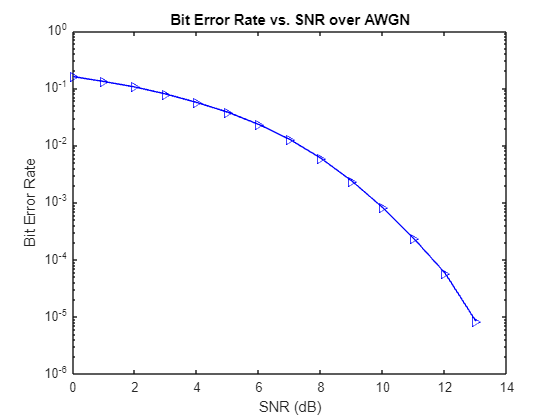

% 
% % Initialize array to store BER values
% total_bit_error_count_array = zeros(length(SNR_vector), 1);
% 
% for snr_index = 1:length(SNR_vector)
%     SNR = SNR_vector(snr_index);
%     total_bit_error_count = 0;
% 
%     for iteration = 1:max_iterations     
%         % Generate data bits
%         data_bits = randi([0 1], (bits_len - num_pilots * log2(modulation_order)), 1);      
% 
%         % Modulate data bits
%         tx_data_symbols = qammod(data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
%         
%         % Combine data symbols with pilot symbols
%         tx_all_symbols = zeros(total_subchannels, 1);
%         tx_all_symbols(pilot_indices) = pilot_symbols;
%         tx_all_symbols(setdiff(1:total_subchannels, pilot_indices)) = tx_data_symbols;        
% 
%         % Perform IFFT
%         tx_data_ifft = ifft(tx_all_symbols, total_subchannels);
%         
%         % Add CP
%         tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];
% 
%         % Transmission through the channel
%         rx_data_ifft_with_guard = tx_data_ifft_with_cp; % Assuming no channel effect
% 
%         % Adding AWGN noise 
%         rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_guard, SNR, 'measured');
% 
%         % Remove CP
%         rx_data_ifft = rx_data_ifft_with_cp_and_noise(cp_length + 1 : total_subchannels + cp_length);
%         rx_data_symbols = fft(rx_data_ifft, total_subchannels);
% 
%         % Remove pilot symbols
%         rx_data_symbols(pilot_indices) = [];
% 
%         % Demodulation
%         rx_data_bits = qamdemod(rx_data_symbols, modulation_order, 'OutputType', 'bit');
% 
%         % Count error bits
%         bit_error_count = sum(rx_data_bits ~= data_bits);
%         total_bit_error_count = total_bit_error_count + bit_error_count ;
%     end
%     % Calculate BER
%     ber = total_bit_error_count / (iteration * data_bits_len);
%     total_bit_error_count_array(snr_index) = ber;
% end
% 
% % Plotting
% figure;
% semilogy(SNR_vector, total_bit_error_count_array, 'b->');
% 
% xlabel('SNR (dB)');
% ylabel('Bit Error Rate');
% title('Bit Error Rate vs. SNR over AWGN');

% Parameter definition
total_subchannels = 64;                        % Total number of subchannels
cp_length = total_subchannels / 4;              % cyclic prefix length
modulation_order = 4;                           % Modulation order
channel_length = 1;                             % Channel length
max_iterations = 1000;                          % Number of iterations in each evaluation
SNR_vector = [0:1:15];                          % Signal-to-noise ratio vector in dB
bits_len = total_subchannels * log2(modulation_order);

% Determine the number of pilot symbols and spacing
num_pilots = min(4, total_subchannels); % Maximum 4 pilot symbols
pilot_spacing = floor(total_subchannels / (num_pilots + 1));

% Generate pilot bits and symbols
pilot_bits_len = num_pilots * log2(modulation_order)

pilot_bits_len = 8

pilot_bits = randi([0 1], pilot_bits_len , 1);
pilot_symbols = qammod(pilot_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);

% Generate indices of pilot symbols
pilot_indices = zeros(num_pilots, 1);
for i = 1:num_pilots
    pilot_indices(i) = i * pilot_spacing;
end

data_bits_len = bits_len - pilot_bits_len;

data_bits_len = 120


data_indices = setxor(1:total_subchannels, pilot_indices); % Indices of data subchannels

data_indices =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


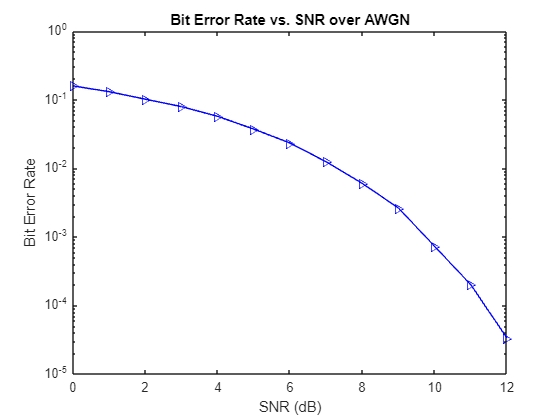


% Initialize array to store BER values
total_bit_error_count_array = zeros(length(SNR_vector), 1);


for snr_index = 1:length(SNR_vector)
    SNR = SNR_vector(snr_index);
    total_bit_error_count = 0;

    for iteration = 1:max_iterations     
        % Generate data bits
        tx_data_bits = randi([0 1], (bits_len - num_pilots * log2(modulation_order)), 1);      

        % Modulate data bits
        tx_data_symbols = qammod(tx_data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
        
        % Combine data symbols with pilot symbols
        tx_all_symbols = zeros(total_subchannels, 1);
        tx_all_symbols(pilot_indices) = pilot_symbols;
        tx_all_symbols(setdiff(1:total_subchannels, pilot_indices)) = tx_data_symbols;        

        % Perform IFFT
        tx_data_ifft = ifft(tx_all_symbols, total_subchannels);
        
        % Add CP
        tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];

        % Transmission through the channel
        rx_data_ifft_with_guard = tx_data_ifft_with_cp; % Assuming no channel effect

        % Adding AWGN noise 
        rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_guard, SNR, 'measured');

        % Remove CP
        rx_data_ifft = rx_data_ifft_with_cp_and_noise(cp_length + 1 : total_subchannels + cp_length);
        
        % Perform FFT
        rx_all_symbols = fft(rx_data_ifft, total_subchannels);

        % Extract data_symbols
        rx_data_symbols = rx_all_symbols(data_indices);

        % Demodulation only data symbols
        rx_data_bits = qamdemod(rx_data_symbols, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count = sum(rx_data_bits ~= tx_data_bits);
        total_bit_error_count = total_bit_error_count + bit_error_count ;
    end
    % Calculate BER
    ber = total_bit_error_count / (iteration * data_bits_len);
    total_bit_error_count_array(snr_index) = ber;
end

% Plotting
figure;
semilogy(SNR_vector, total_bit_error_count_array, 'b->');

xlabel('SNR (dB)');
ylabel('Bit Error Rate');
title('Bit Error Rate vs. SNR over AWGN');

% % Parameter definition
% total_subchannels = 16;                        % Total number of subchannels
% cp_length = total_subchannels / 4;              % cyclic prefix length
% modulation_order = 4;                           % Modulation order
% channel_length = 1;                             % Channel length
% max_iterations = 1000;                          % Number of iterations in each evaluation
% SNR_vector = [0:1:15];                          % Signal-to-noise ratio vector in dB
% bits_len = total_subchannels * log2(modulation_order);
% 
% % Determine the number of pilot symbols and spacing
% num_pilots = min(4, total_subchannels); % Maximum 4 pilot symbols
% pilot_spacing = floor(total_subchannels / (num_pilots + 1));
% 
% % Generate pilot bits and symbols
% pilot_bits = randi([0 1], num_pilots * log2(modulation_order), 1);
% pilot_symbols = qammod(pilot_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
% 
% % Initialize array to store BER values
% total_bit_error_count_array = zeros(length(SNR_vector), 3);
% for gain=1:3
%     for snr_index = 1:length(SNR_vector)
%         SNR = SNR_vector(snr_index);
%         total_bit_error_count = 0;
%     
%         for iteration = 1:max_iterations     
%             % Generate data bits
%             data_bits = randi([0 1], (bits_len - num_pilots * log2(modulation_order)), 1);      
%     
%             % Modulate data bits
%             tx_data_symbols = qammod(data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
%             
%             % Combine data symbols with pilot symbols
%             tx_all_symbols = zeros(total_subchannels, 1);
%             tx_all_symbols(pilot_indices) = pilot_symbols;
%             tx_all_symbols(setdiff(1:total_subchannels, pilot_indices)) = tx_data_symbols;        
%     
%             % Perform IFFT
%             tx_data_ifft = ifft(tx_all_symbols, total_subchannels);
%             
%             % Add CP
%             tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];
%     
%             % Transmission through the channel
%             rx_data_ifft_with_guard = tx_data_ifft_with_cp * 1; % Assuming no channel effect
%     
%             % Adding AWGN noise 
%             rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_guard, SNR, 'measured');
%     
%             % Remove CP
%             rx_data_ifft = rx_data_ifft_with_cp_and_noise(cp_length + 1 : total_subchannels + cp_length);
%             rx_data_symbols = fft(rx_data_ifft, total_subchannels);
%     
%             % Remove pilot symbols
%             rx_data_symbols(pilot_indices) = [];
%     
%             % Demodulation
%             rx_data_bits = qamdemod(rx_data_symbols, modulation_order, 'OutputType', 'bit');
%     
%             % Count error bits
%             bit_error_count = sum(rx_data_bits ~= data_bits);
%             total_bit_error_count = total_bit_error_count + bit_error_count ;
%         end
%         % Calculate BER
%         ber = total_bit_error_count / (iteration * bits_len);
%         total_bit_error_count_array(snr_index, gain) = ber;
%     end
% end
% 
% % Plotting
% figure;
% semilogy(SNR_vector, total_bit_error_count_array(:,1), 'b->');
% 
% hold on;
% semilogy(SNR_vector, total_bit_error_count_array(:,2), 'r-o');
% 
% semilogy(SNR_vector, total_bit_error_count_array(:,3), 'g-^');
% 
% xlabel('SNR (dB)');
% ylabel('Bit Error Rate');
% title('Bit Error Rate vs. SNR over AWGN');
% hold off;